% Stage 1: Load MeanRGB and CosRGB from 4 image files.

dir = 'cut';
file = 'potdng';
fun = @(x) rgb2lin(double(x) ./ 255.0);

% dir = 'canoncut/day3';
% file = 'bright';
% fun = @(x) rgb2lin(double(x) ./ 255.0);

[Y, X, ~] = size(imread(strcat(dir, '/', file, '0.tif')));
ims = gpuArray(zeros(4, Y, X, 3, 'double'));

MultipleOf = 64;
YAdd = MultipleOf - mod(Y - 1, MultipleOf) - 1;
XAdd = MultipleOf - mod(X - 1, MultipleOf) - 1;

clear MultipleOf;
clear Y;
clear X;

for x=0:3
    deg = num2str(45 * x);
    ims(x+1, :, :, :) = fun(imread(strcat(dir, '/', file, deg, '.tif')));
end

clear deg;
clear x;
clear dir;
clear fun;

imsmax = ims;
imsmax(1, :, :, :) = imsmax(2, :, :, :) + imsmax(4, :, :, :) - imsmax(3, :, :, :);
imsmax(2, :, :, :) = imsmax(1, :, :, :) + imsmax(3, :, :, :) - imsmax(4, :, :, :);
imsmax(3, :, :, :) = imsmax(2, :, :, :) + imsmax(4, :, :, :) - imsmax(1, :, :, :);
imsmax(4, :, :, :) = imsmax(1, :, :, :) + imsmax(3, :, :, :) - imsmax(2, :, :, :);
ims = max(ims, imsmax);
clear imsmax;

imsfft = fft(ims, 4, 1) * 0.5;
clear ims;

MeanRGB = squeeze(abs(imsfft(1, :, :, :))) * 0.5; % 0.5 * Diffuse + 0.5 * Perp + 0.5 * Parallel
CosRGB = squeeze(abs(imsfft(2, :, :, :))); % 0.5 * (Perp - Parallel)
%Phase = squeeze(angle(imsfft(2, :, :, :)));
clear imsfft;

MirrSize = [YAdd XAdd] / 2;
clear YAdd;
clear XAdd;

% Prevents CosRGB > MeanRGB due to [1.0 1.0 0.0 0.0] giving Amp > Mean.
CosRGB = min(MeanRGB, CosRGB);

% Pad to get a nice size.
MeanRGB = padarray(MeanRGB, MirrSize, 'symmetric', 'both');
CosRGB = padarray(CosRGB, MirrSize, 'symmetric', 'both');
%Phase = padarray(Phase, MirrSize, 'symmetric', 'both');
clear MirrSize;

imshow(lin2rgb(gather(MeanRGB)));
imshow(lin2rgb(gather(CosRGB)));

% Stage 2: Initial estimate using tiling.
tic;

[qyTotal, qxTotal, ~] = size(MeanRGB);
halfSize = 8;
tileSize = halfSize * 2;
qyTiles = qyTotal / halfSize;
qxTiles = qxTotal / halfSize;

SpecularFactor = gpuArray(zeros([qyTotal, qxTotal], 'double'));
SpectralFactorWeights = gpuArray(zeros([qyTotal, qxTotal], 'double'));

% Cos window used for weights.
CosWindow = 0.5 - 0.5 .* cos(pi / tileSize + linspace(0, 2 * pi * (tileSize - 1) / tileSize, tileSize));
CosWindow = CosWindow' * CosWindow;

% 2D Coord Arrays for each tile.
yCoords = (0:qyTiles-2)' * halfSize + (1:tileSize);
xCoords = (0:qxTiles-2)' * halfSize + (1:tileSize);

MeanRGBTiles = reshape(MeanRGB(yCoords, xCoords, :), [qyTiles-1, tileSize, qxTiles-1, tileSize, 3]);
CosRGBTiles = reshape(CosRGB(yCoords, xCoords, :), [qyTiles-1, tileSize, qxTiles-1, tileSize, 3]);

% The tiles to compare.
MeanRGBTilesGrad = MeanRGBTiles - mean(MeanRGBTiles, [2 4]);
CosRGBTilesGrad = CosRGBTiles - mean(CosRGBTiles, [2 4]);

% Add window to gradients.
CosWindowMult = gpuArray(zeros([1 tileSize 1 tileSize 1]));
CosWindowMult(1, :, 1, :, 1) = CosWindow;
MeanRGBTilesGrad = MeanRGBTilesGrad .* CosWindowMult;
CosRGBTilesGrad = CosRGBTilesGrad .* CosWindowMult;
clear CosWindowMult;

% Do tile comparison.
CorrNum = sum(CosRGBTilesGrad .* MeanRGBTilesGrad, [2 4 5]);
CorrDenom = sum(CosRGBTilesGrad .* CosRGBTilesGrad, [2 4 5]);
CorrVals = squeeze(CorrNum ./ max(0.001, CorrDenom));

% For each point in the window, sum up the weighted values.
for yWin = 1:tileSize
    yCoords2 = (0:qyTiles-2) * halfSize + yWin;
    for xWin = 1:tileSize
        xCoords2 = (0:qxTiles-2) * halfSize + xWin;
        CosWindowVal = CosWindow(yWin, xWin);
        
        SpecularFactor(yCoords2, xCoords2) = SpecularFactor(yCoords2, xCoords2) + CosWindowVal .* CorrVals;
        SpectralFactorWeights(yCoords2, xCoords2) = SpectralFactorWeights(yCoords2, xCoords2) + CosWindowVal;
    end
end

SpecularFactor = max(1.0, SpecularFactor ./ SpectralFactorWeights);

toc;

Elapsed time is 0.454981 seconds.



clear qyTotal;
clear qxTotal;
clear halfSize;
clear tileSize;
clear qyTiles;
clear qxTiles;
clear CosWindow;
clear yTile;
clear xTile;
clear yCoords;
clear yCoords2;
clear xCoords;
clear xCoords2;
clear yWin;
clear xWin;
clear MeanRGBTiles;
clear CosRGBTiles;
clear MeanRGBTilesGrad;
clear CosRGBTilesGrad;
clear CorrNum;
clear CorrDenom;
clear CorrTile;
clear CosWindowVal;
clear SpectralFactorWeights;

imshow(lin2rgb(gather(0.25 .* (CorrVals - 1.0))));
imshow(lin2rgb(gather(0.25 .* (SpecularFactor - 1.0))));
imshow(lin2rgb(gather(CosRGB .* SpecularFactor)));
imshow(lin2rgb(gather(MeanRGB - CosRGB .* SpecularFactor)));

% Stage 3: Improve the estimate iteratively using line-projection.

tic;

[qyTotal, qxTotal, ~] = size(MeanRGB);
divCount = 4;
qyPart = qyTotal / divCount;
qxPart = qxTotal / divCount;

% Projection onto nearest colour plane.
CosFactor_Max = min(max(0.0001, MeanRGB) ./ max(0.0001, CosRGB), [], 3);

% Set to 1.0 when polarization is very small.
%BinaryMap = euclidianlength(CosRGB, 3) > 0.01;
%BinaryMap = imdilate(BinaryMap, strel('disk', 1));
%CosFactor_Max = BinaryMap .* CosFactor_Max + (1 - BinaryMap) .* 1.0;
%clear BinaryMap;

CosFactor = min(CosFactor_Max, SpecularFactor);

% Init pyramids.
PyrLevel = 4;
MeanRGBPyr = pyramidgaussian(MeanRGB, PyrLevel);
CosRGBPyr = pyramidgaussian(max(0.001, CosRGB), PyrLevel);

CosFactorPyr = pyramidlaplacian(CosFactor, PyrLevel);
clear CosFactor;

CosFactorPyr_Max = pyramidgaussian(CosFactor_Max, PyrLevel);
clear CosFactor_Max;

toc;

Elapsed time is 0.035115 seconds.



sigma_spatial_1 = 2.33;
sigma_spatial_2 = 0.75;
sigma_tonal = 0.02;

% For each level of the pyramid.
while PyrLevel >= 1
    PyrLevelDiv = 2 ^ (PyrLevel - 1);
    qyPartDiv = qyPart / PyrLevelDiv;
    qxPartDiv = qxPart / PyrLevelDiv;
    
    tic;
    IterCount1 = 2 * PyrLevel;
    for i = 1:IterCount1
        % Iterative improvements.
        DiffuseRGB = MeanRGBPyr{PyrLevel} - CosFactorPyr{PyrLevel} .* CosRGBPyr{PyrLevel};
        CosFactorCopy = bilateralx(CosFactorPyr{PyrLevel}, DiffuseRGB, sigma_spatial_1, sigma_tonal);
        
        %CosFactorCopy = CosFactorPyr{PyrLevel};
        
        % First, bring the diffuse components close together.
        for qy = 0:(divCount-1)
            yOffset = qyPartDiv * qy;
            yCoords = (yOffset+1):(yOffset+qyPartDiv);
            for qx = 0:(divCount-1)
                xOffset = qxPartDiv * qx;
                xCoords = (xOffset+1):(xOffset+qxPartDiv);
                
                CosFactorPyr{PyrLevel}(yCoords, xCoords) = bilaterallinex(...
                    yCoords, xCoords, MeanRGBPyr{PyrLevel}, CosRGBPyr{PyrLevel}, CosFactorCopy, ...
                    1.0, CosFactorPyr_Max{PyrLevel}(yCoords, xCoords), sigma_spatial_2, sigma_tonal);
            end
        end
    end
    
    % Bilateral-filter the resulting polarization map.
    IterCount2 = PyrLevel;
    for i = 1:IterCount2
        % Do this with the Mean to diffuse towards edges.
        % DiffuseRGB = MeanRGBPyr{PyrLevel} - CosFactorPyr{PyrLevel} .* CosRGBPyr{PyrLevel};
        CosFactorPyr{PyrLevel} = bilateralx(...
            CosFactorPyr{PyrLevel}, MeanRGBPyr{PyrLevel}, sigma_spatial_1, sigma_tonal);
    end
    toc;
    
    if PyrLevel > 1
        CosFactorPyr = pyramidupscale(CosFactorPyr);
    else
        CosFactor = CosFactorPyr{1};
    end
    
    PyrLevel = PyrLevel - 1;
end

Elapsed time is 6.192322 seconds.
Elapsed time is 4.731380 seconds.
Elapsed time is 5.415464 seconds.
Elapsed time is 6.520993 seconds.



clear IterCount1;
clear DiffuseRGB;
clear CosFactorCopy;

clear PyrLevel;
clear PyrLevelDiv;
clear qyPartDiv;
clear qxPartDiv;
clear MeanRGBPyr;
clear CosRGBPyr;
clear CosFactorPyr;
clear CosFactorPyr_Max;

clear sigma_spatial_1;
clear sigma_spatial_2;
clear sigma_tonal;
clear IterCount2;
clear i;

clear qyTotal;
clear qxTotal;
clear qyPart;
clear qxPart;
clear divCount;

clear qy;
clear qx;
clear yCoords;
clear yOffset;
clear xCoords;
clear xOffset;

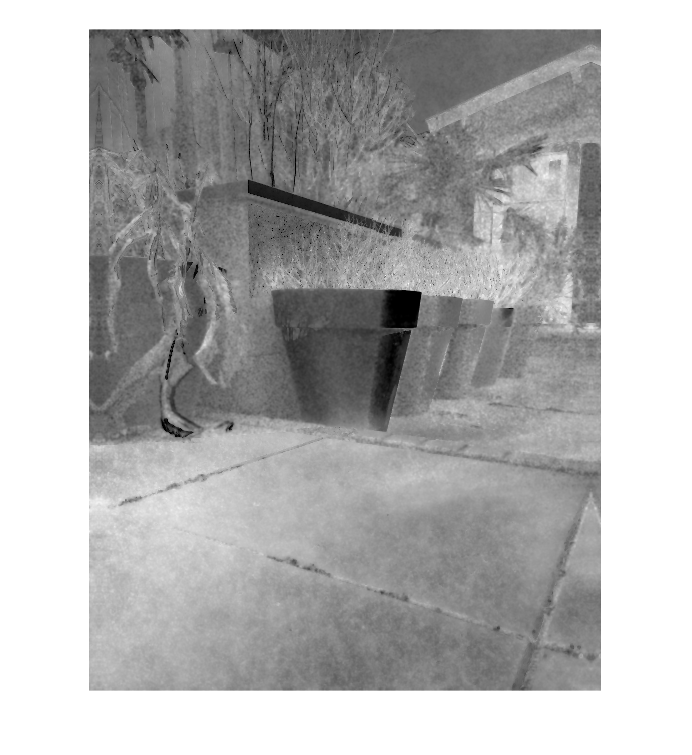

%imshow(lin2rgb(gather(0.25 .* (CosFactorOG - 1.0))));
imshow(lin2rgb(gather(0.25 .* (CosFactor - 1.0))));

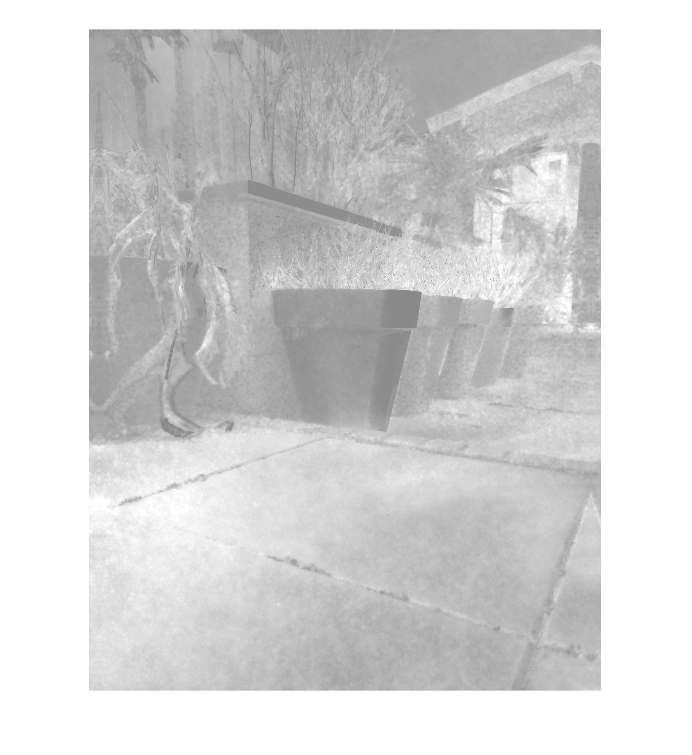

imshow(lin2rgb(gather(0.25 .* (CosFactor))));

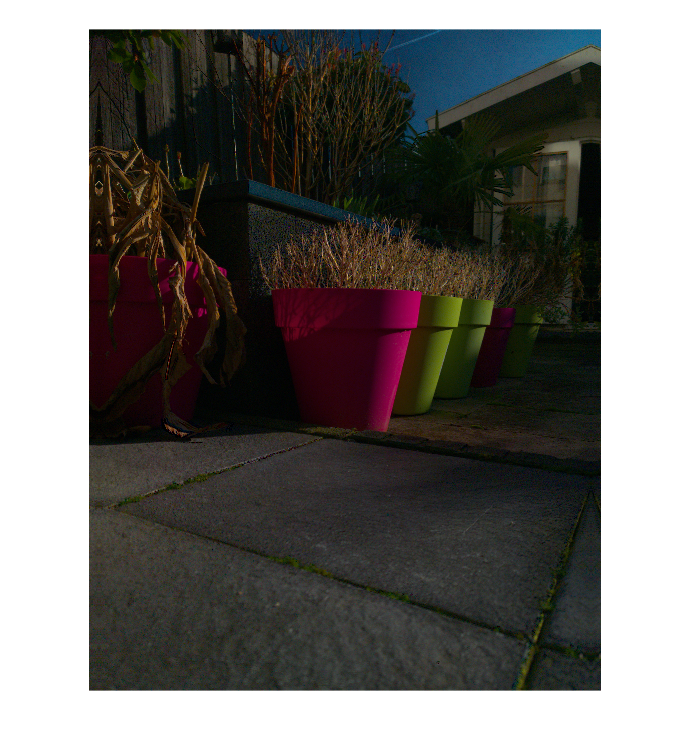

%imshow(lin2rgb(gather(0.25 .* (CosFactor_Max - 1.0))));

Specular = max(0.0, CosFactor .* CosRGB);
Diffuse = max(0.0, MeanRGB - Specular);

imshow(lin2rgb(gather(Diffuse)));

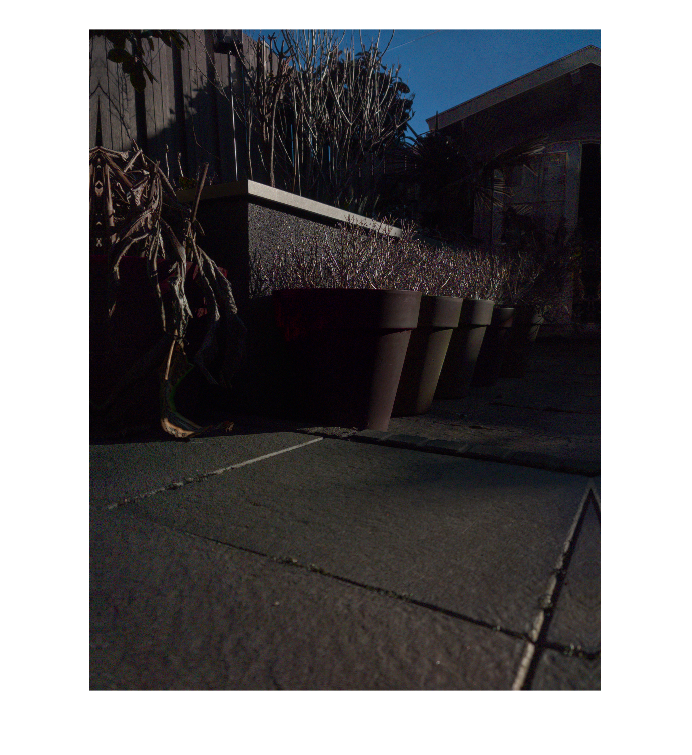

imshow(lin2rgb(gather(Specular)));


imwrite(double(lin2rgb(gather(Diffuse))), 'algo/dif2.tif');
imwrite(double(lin2rgb(gather(Specular))), 'algo/spec2.tif');

% HSV(:, :, 1) = (Phase(:, :, 1) ./ pi + 1.0) ./ 2.0;
% HSV(:, :, 2) = 1.0;
% HSV(:, :, 3) = min(1.0, 100 .* CosRGB(:, :, 1));
% 
% imshow(hsv2rgb(gather(HSV)));

imshowphase(CosRGB, Phase, 1);
imshowphase(CosRGB, Phase, 2);
imshowphase(CosRGB, Phase, 3);

%imshow(lin2rgb(gather((Phase ./ 2.0 ./ pi) + 0.5)));

imshow(lin2rgb(gather(CosRGB)));

BinaryMap = euclidianlength(CosRGB, 3) > 0.01;
BinaryMap = imdilate(BinaryMap, strel('disk', 1));
BinaryMap = imgaussfilt(single(BinaryMap), 0.71);

imshow(lin2rgb(gather(single(BinaryMap))));

MeanRGB = imresize(MeanRGB, 0.5);
CosRGB = imresize(CosRGB, 0.5);

[ny, nx, ~] = size(MeanRGB);

totals = gpuArray(zeros(ny, nx, 'single'));
weights = gpuArray(zeros(ny, nx, 'single'));

radius = 3;
for dy = -radius:radius
    cy = max(1, min(ny, (1:ny) + dy));
    for dx = -radius:radius
        cx = max(1, min(nx, (1:nx) + dx));
        
        MeanRGB_Shifted = MeanRGB(cy, cx, :);
        CosRGB_Shifted = CosRGB(cy, cx, :);
        
        Diff_Start = MeanRGB - MeanRGB_Shifted;
        Diff_Add = CosRGB - CosRGB_Shifted;
        
        % How many times to add "Add" to "Start" for smallest vector?
        % Decompose Start into two orthogonal vectors: Add and Orthogonal_Add
        % Project Start onto Add to find how often Add is included.
        
        StartProjAdd1 = dot(Diff_Start, Diff_Add, 3);
        StartProjAdd2 = dot(Diff_Add, Diff_Add, 3);
        StartProjAdd = StartProjAdd1 ./ max(0.0001, StartProjAdd2);
        
        % This is how much it is included. By removing it, you minimize the
        % Start vector by only keeping the orthogonal vector.
        
        Valid = StartProjAdd2 > 0 & StartProjAdd > 0;
        
        %totals = max(totals, Valid .* StartProjAdd);
        
        weight = single(Valid);
        
        totals = totals + weight .* StartProjAdd;
        weights = weights + weight;
    end
end

%CosFactor = totals;

CosFactor = totals ./ max(0.0001, weights);

clear MeanRGB_Shifted;
clear CosRGB_Shifted;
clear CosFactor_Shifted;
clear Diff_Start;
clear Diff_Add;

imshow(lin2rgb(gather(0.25 .* CosFactor)));
imshow(lin2rgb(gather(0.25 .* max(1.0, CosFactor))));

imshow(lin2rgb(gather(MeanRGB)));
imshow(lin2rgb(gather(MeanRGB - CosFactor .* CosRGB)));
imshow(lin2rgb(gather(MeanRGB - max(1.0, CosFactor) .* CosRGB)));
imshow(lin2rgb(gather(max(1.0, CosFactor) .* CosRGB)));

CosFactor(1:100, 1:100)

weights(1:100, 1:100)